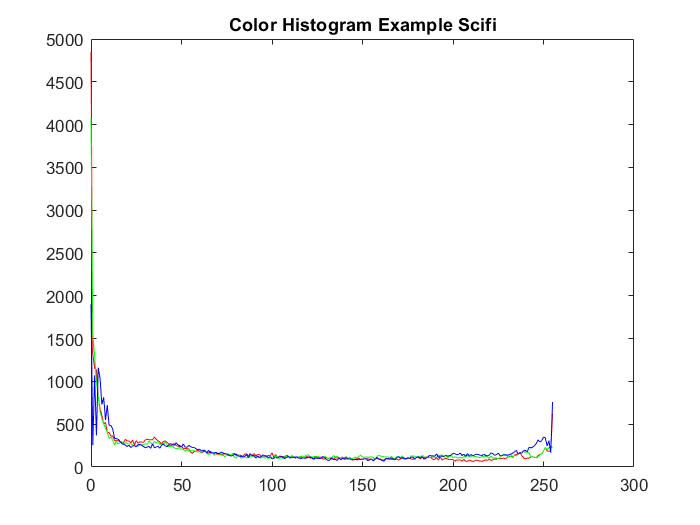

myFolder = 'C:\Users\kfoster\Desktop\QEA\QEA_Module_2\Posters\Scifi\Train';
if ~isdir(myFolder)
  errorMessage = sprintf('Error: The following folder does not exist:\n%s', myFolder);
  uiwait(warndlg(errorMessage));
  return;
end
filePattern = fullfile(myFolder, '*.jpg');
jpegFiles = dir(filePattern);
totalRed = zeros(268,182);
totalGreen = zeros(268,182);
totalBlue = zeros(268,182);
for k = 1:length(jpegFiles)
  baseFileName = jpegFiles(k).name;
  fullFileName = fullfile(myFolder, baseFileName);
  %fprintf(1, 'Now analyzing %s\n', fullFileName);
  image = imread(fullFileName);
  % Split into RGB channesl
  Red = image(:,:,1);
  Green = image(:,:,2);
  Blue = image(:,:,3);
  %Get histValues for each channel
  [yRed, x] = imhist(Red);
  [yGreen, x] = imhist(Green);
  [yBlue, x] = imhist(Blue);
  %Plot them together in one plot
  plot(x, yRed, 'Red', x, yGreen, 'Green', x, yBlue, 'Blue');
  title("Color Histogram Example Scifi");
  totalRed = totalRed + double(Red);
  totalGreen = totalGreen + double(Green);
  totalBlue = totalBlue + double(Blue);
end

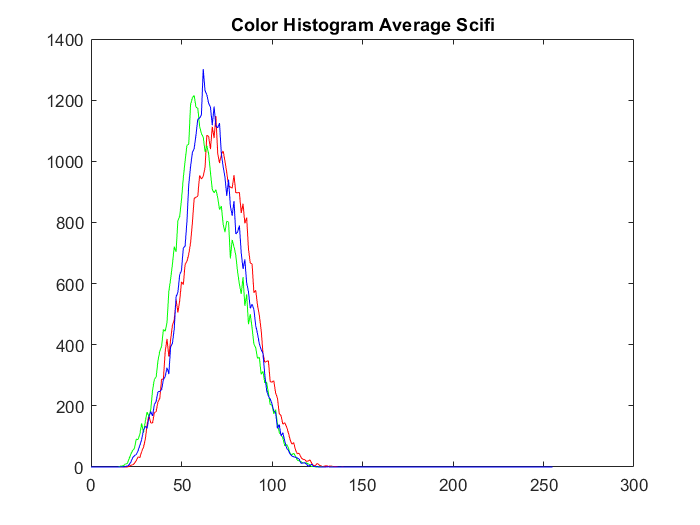


avgRed = totalRed./length(jpegFiles);
avgGreen = totalGreen./length(jpegFiles);
avgBlue = totalBlue./length(jpegFiles);
[yavgRed, x] = imhist(uint8(avgRed));
[yavgGreen, x] = imhist(uint8(avgGreen));
[yavgBlue, x] = imhist(uint8(avgBlue));

plot(x, yavgRed, 'Red', x, yavgGreen, 'Green', x, yavgBlue, 'Blue');
title("Color Histogram Average Scifi");

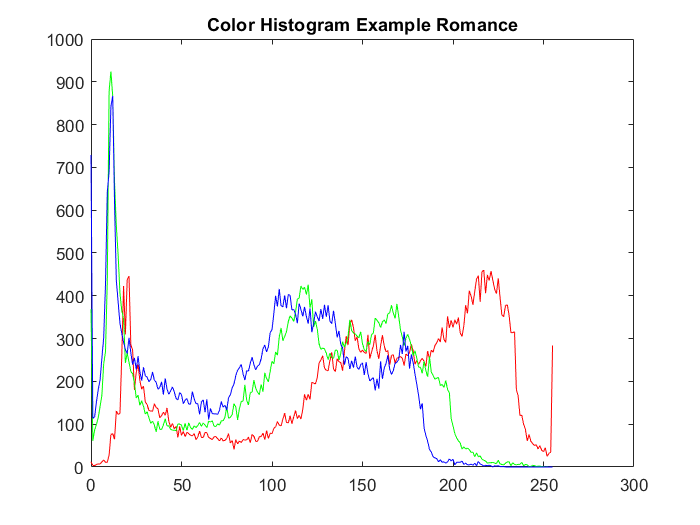

myFolder = 'C:\Users\kfoster\Desktop\QEA\QEA_Module_2\Posters\Romance\Train';
if ~isdir(myFolder)
  errorMessage = sprintf('Error: The following folder does not exist:\n%s', myFolder);
  uiwait(warndlg(errorMessage));
  return;
end
filePattern = fullfile(myFolder, '*.jpg');
jpegFiles = dir(filePattern);
totalRed = zeros(268,182);
totalGreen = zeros(268,182);
totalBlue = zeros(268,182);
for k = 1:length(jpegFiles)
  baseFileName = jpegFiles(k).name;
  fullFileName = fullfile(myFolder, baseFileName);
  %fprintf(1, 'Now analyzing %s\n', fullFileName);
  image = imread(fullFileName);
  % Split into RGB channesl
  Red = image(:,:,1);
  Green = image(:,:,2);
  Blue = image(:,:,3);
  %Get histValues for each channel
  [yRed, x] = imhist(Red);
  [yGreen, x] = imhist(Green);
  [yBlue, x] = imhist(Blue);
  %Plot them together in one plot
  plot(x, yRed, 'Red', x, yGreen, 'Green', x, yBlue, 'Blue');
  title("Color Histogram Example Romance");
  totalRed = totalRed + double(Red);
  totalGreen = totalGreen + double(Green);
  totalBlue = totalBlue + double(Blue);
end

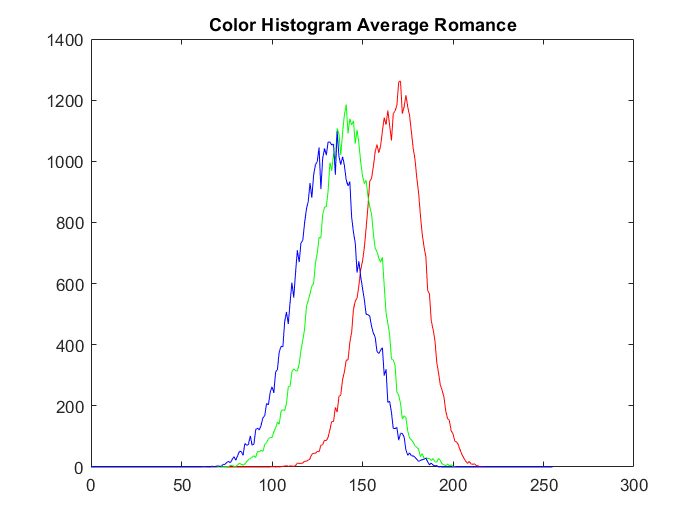


avgRed = totalRed./length(jpegFiles);
avgGreen = totalGreen./length(jpegFiles);
avgBlue = totalBlue./length(jpegFiles);
[yavgRed, x] = imhist(uint8(avgRed));
[yavgGreen, x] = imhist(uint8(avgGreen));
[yavgBlue, x] = imhist(uint8(avgBlue));

plot(x, yavgRed, 'Red', x, yavgGreen, 'Green', x, yavgBlue, 'Blue');
title("Color Histogram Average Romance");